# Part-IV 交织的使用与效果呈现

clear all, close all, clc

# *****在此处修改参数*****

#### mbit: 映射比特数（2）

#### casenum: 场景1/2/3/4

    (1)b=pho=0; (2)b=pho=1; (3)b=0.7, pho=0.996; (4)b=0.3, pho=0.9

#### block_size: 交织分块的大小

mbit = 2;
casenum = 4;
block_size = 300;

## `I. 针对以下编码策略进行编译码:`

- `不编码`

- `仅采用`(8, 3, 4)`码`

- `仅采用`1/2`效率卷积码`

`注1:使用同一种``2`** bit/**`符号映射方式``通过``信道（场景一/二/三,条件一）``,最终的误比特率对比各策略的性能效果`

`注2:对于随机产生的信息比特流, 编码前交织似乎无意义; 但若采用有意义的信息流, 能否起到一定效果?`

`注3:本实验中控制SNR的方式位``通过改变信道噪声能量期望大小控制SNR``,不同于其他部分通过改变映射矩阵调整能量功率来控制SNR的方式(但由于一些未知的原因,似乎对1比特映射不太有效)`

T=5;
N = 3000;
x = randi(2, 1, N)-1;
crc_code = x;
A_2 = [1 1 0 1
     1 1 1 1]';
snr_low = -5;
snr_high = 45;
snr_step = 1;
Mmap1= [  -1  0;    1  0 ];
Mmap2 = [ -1 -1;    -1  1;    1 -1;    1  1 ];
Mmap3= sqrt(2)*[cos(pi/8*[-5,-7,5,7,-3,-1,3,1]'),sin(pi/8*[-5,-7,5,7,-3,-1,3,1]')];
A=sqrt(1/2);
switch mbit
    case 1
        Mmap=A*Mmap1;
    case 2
        Mmap=A*Mmap2;
    otherwise
        Mmap=A*Mmap3;
end
% 编码: none / conv / (8,3,4)
code_none = crc_code;
code_834 = linear_encode(crc_code);
code_conv2 = conv_encode(crc_code, A_2, 1);
% SNR取值集
snr_dB = snr_low:snr_step:snr_high;

### A) 编码后不交织

BER1 = repmat(snr_dB*0, [5 1]);          % 误码率记录矩阵: 编码策略数 × SNR取值数
for i=1:length(snr_dB)
    snr = 10^(snr_dB(i)/10);
    % 映射
    u_none = mapping(code_none, 0, mbit, Mmap);
    u_834 = mapping(code_834, 0, mbit, Mmap);
    u_conv2 = mapping(code_conv2, 0, mbit, Mmap);
    % 信道传输
    v_none = channel_snr(u_none, T, size(u_none, 2), snr, casenum);
    v_834 = channel_snr(u_834, T, size(u_834, 2), snr, casenum);
    v_conv2 = channel_snr(u_conv2, T, size(u_conv2, 2), snr, casenum);
    % 解映射
    bit_none = mapping(v_none, 1, mbit, Mmap);
    bit_834 = mapping(v_834, 1, mbit, Mmap);
    bit_conv2 = mapping(v_conv2, 1, mbit, Mmap);
    % 硬判决译码
    h_none = bit_none;                                  % none
    h_834 = linear_decode(bit_834);                     % (8,3,4)
    h_conv2 = viterbi(bit_conv2, A_2, 1, "hard", Mmap); % conv2
    BER1(1,i)=sum(abs(h_none-x))/N;
    BER1(2,i)=sum(abs(h_834-x))/N;
    BER1(3,i)=sum(abs(h_conv2-x))/N;
end
save("Data\PartIV_EncodingModes.mat", "N", "snr_dB", "BER1");

### B) 编码后交织

% 交织(由于是1-bit映射,所以和映射顺序调换也没有关系)
code_none = interweave(code_none, 0, block_size);
code_834 = interweave(code_834, 0, block_size);
code_conv2 = interweave(code_conv2, 0, block_size);

BER = repmat(snr_dB*0, [5 1]);          % 误码率记录矩阵: 编码策略数 × SNR取值数
Mmap = Mmap2;
for i=1:length(snr_dB)
    snr=10^(snr_dB(i)/10);
    % Mmap同前
    % 映射
    u_none = mapping(code_none, 0, mbit, Mmap);
    u_834 = mapping(code_834, 0, mbit, Mmap);
    u_conv2 = mapping(code_conv2, 0, mbit, Mmap);
    % 信道传输
    v_none = channel_snr(u_none, T, size(u_none, 2), snr, casenum);
    v_834 = channel_snr(u_834, T, size(u_834, 2), snr, casenum);
    v_conv2 = channel_snr(u_conv2, T, size(u_conv2, 2), snr, casenum);
    % 解映射
    bit_none = mapping(v_none, 1, mbit, Mmap);
    bit_834 = mapping(v_834, 1, mbit, Mmap);
    bit_conv2 = mapping(v_conv2, 1, mbit, Mmap);
    % 解交织
    bit_none = interweave(bit_none, 1, block_size);
    bit_834 = interweave(bit_834, 1, block_size);
    bit_conv2 = interweave(bit_conv2, 1, block_size);
    % 硬判决译码
    h_none = bit_none;                                  % none
    h_834 = linear_decode(bit_834);                     % (8,3,4)
    h_conv2 = viterbi(bit_conv2, A_2, 1, "hard", Mmap); % conv2
    % 各自统计误码率并按none, 834, conv2的顺序存入BER
    BER(1,i)=sum(abs(h_none-x))/N;
    BER(2,i)=sum(abs(h_834-x))/N;
    BER(3,i)=sum(abs(h_conv2-x))/N;
end
save("Data\PartIV_interweave_123_channel.mat", "N", "snr_dB", "BER");

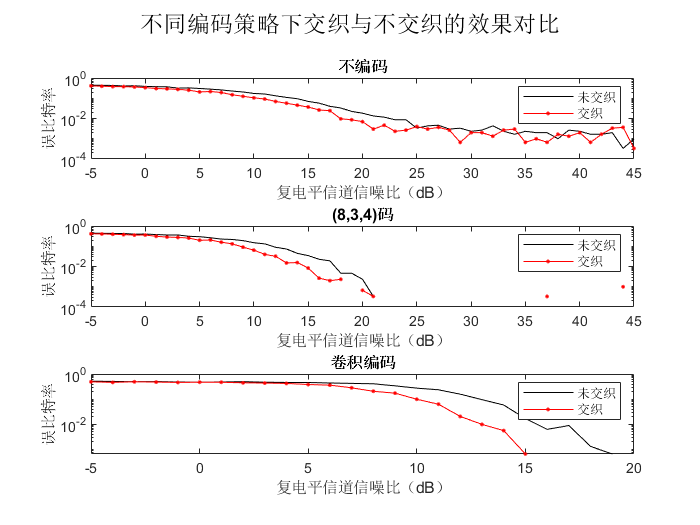

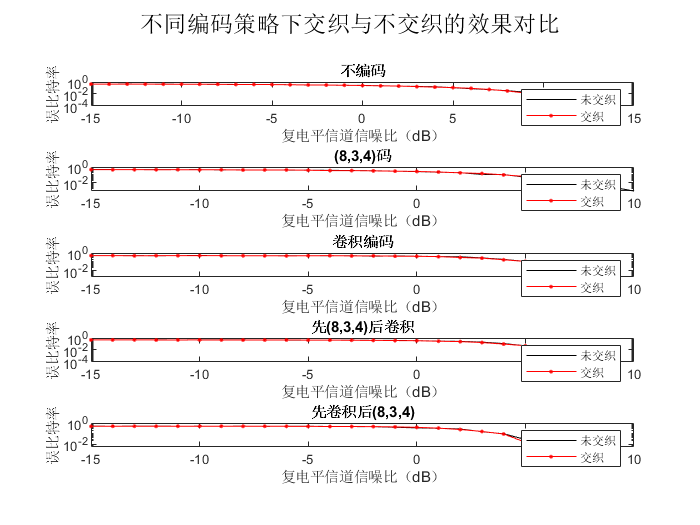

clear all, close all, clc
data1 = load("Data\PartIV_EncodingModes.mat");
data0 = load("Data\PartIV_interweave_123_channel.mat");
snr_dB = data0.snr_dB;
BER1 = data1.BER1;  % 不交织
BER = data0.BER;    % 交织
% 绘图
figure;
subplot(3,1,1);
semilogy(snr_dB,BER1(1,:), 'k-', snr_dB,BER(1,:), 'r.-');
legend( '未交织','交织');
xlabel('复电平信道信噪比（dB）');
ylabel('误比特率');
title('不编码')
subplot(3,1,2);
semilogy(snr_dB,BER1(2,:), 'k-', snr_dB,BER(2,:), 'r.-');
legend( '未交织','交织');
xlabel('复电平信道信噪比（dB）');
ylabel('误比特率');
title('(8,3,4)码')
subplot(3,1,3);
semilogy(snr_dB,BER1(3,:), 'k-', snr_dB,BER(3,:), 'r.-');
legend( '未交织','交织');
xlabel('复电平信道信噪比（dB）');
ylabel('误比特率');
title('卷积编码')
sgtitle("不同编码策略下交织与不交织的效果对比");